%folder
imageFolder = 'imagemitsuba/cu_0.025/';
% 画像フォルダ内の.matファイルを取得
imageFiles = dir(fullfile(imageFolder, '*.mat')); % フォーマットに応じて変更

figure;

% filePath
matFilePath = fullfile(imageFolder, imageFiles(7).name);
data = load(matFilePath);


cform1 = makecform('xyl2xyz')

cform1 = フィールドをもつ struct :
            c_func: @xyl2xyz
     ColorSpace_in: 'xyl'
    ColorSpace_out: 'xyz'
          encoding: 'double'
             cdata: [1×1 struct]


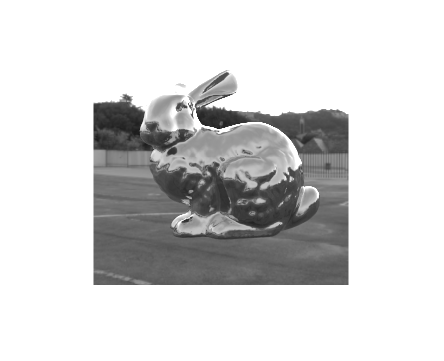


xyYImg = data.image_np_xyY; 

xyzImg1 = applycform(xyYImg,cform1);
rgbImg1 = xyz2rgb(xyzImg1);
imshow(rgbImg1);


xyYImg(:,:,1) = 0.3127;
xyYImg(:,:,2) = 0.3290;
LDR_xyY = ReinhardTMO(xyYImg(:,:,3));
xyY_aft = cat(3,xyYImg(:,:,1), xyYImg(:,:,2), LDR_xyY)

xyY_aft = xyY_aft(:,:,1) =

    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127    0.3127  

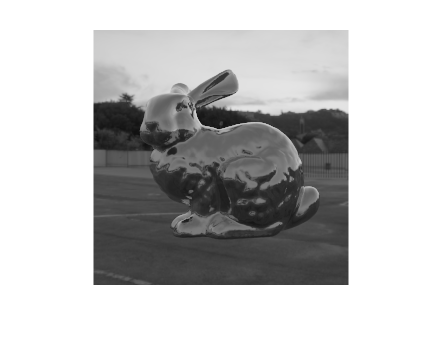

xyzImg = applycform(xyY_aft,cform1);
rgbImg = xyz2rgb(xyzImg);
imshow(rgbImg);